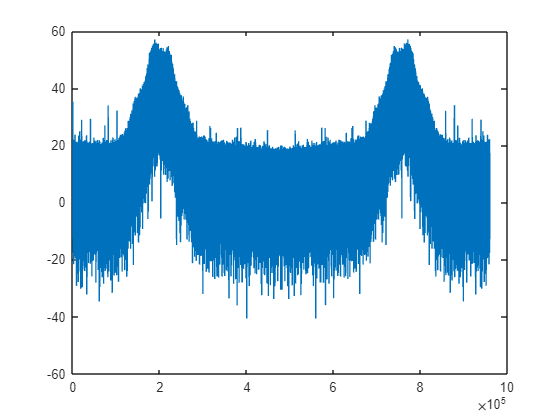

clear; 
close all;
syms x t cs xc xl f1 xs xls xlsj xn xz xzs y yn ys
load("Radio_signal.mat")

x = raw_radio_94_2MHz;
Fs = 960000;
Fc = 200000;
t = 0:(1/Fs):10;
plot(20*log10(abs(fft(x, Fs))))

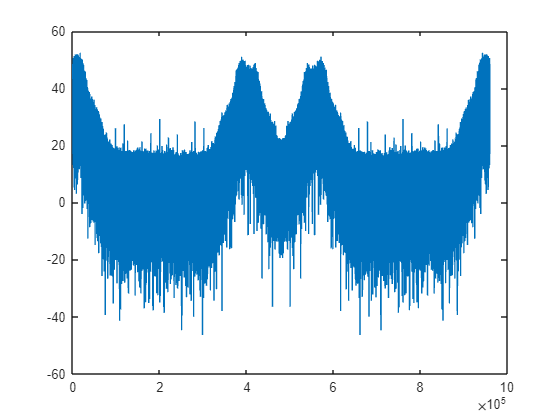

x = x(1:length(t));
cs = cos(2*pi*Fc*t);
xc = x'.*cs;
plot(20*log10(abs(fft(xc, Fs))))

f1 = fir1(16, 0.03125);

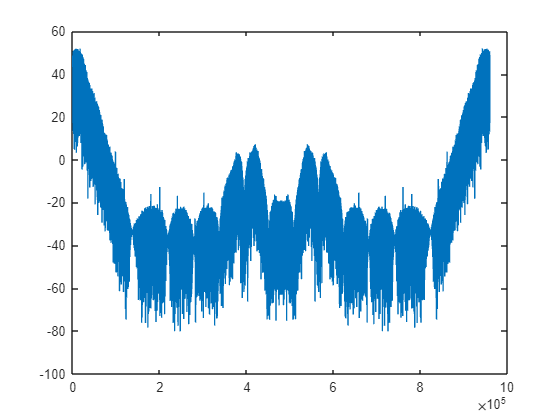

xl = filter(f1, 1, xc);
plot(20*log10(abs(fft(xl, Fs))))

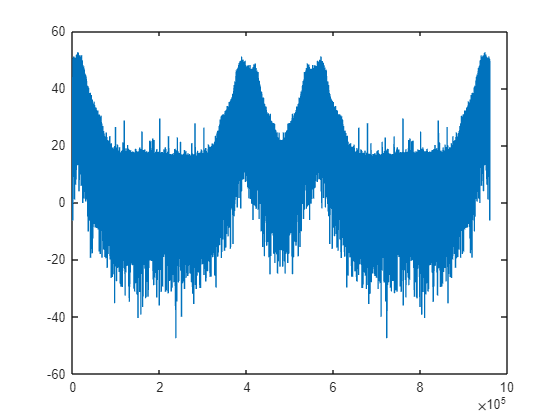

si = -sin(2*pi*Fc*t);
xs = x'.*si;
plot(20*log10(abs(fft(xs, Fs))))

xls = filter(f1, 1, xs);
xlsj = xls * 1j;

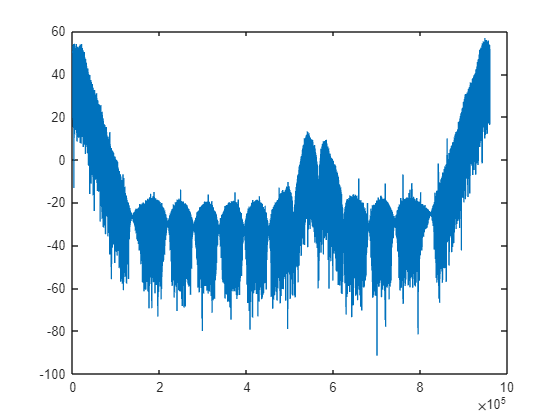

xn = xlsj + xl;
plot(20*log10(abs(fft(xn, Fs))))

xz = circshift(xn, -1);
xzs = conj(xz);
y = xn.*xzs;
yn = angle(y);

ys = downsample(yn, 5);
sound(ys, 192000)